a) 

i. Note the training sample has size: background-->1053; foreground-->250. The histogram estimate for the priors P(y) shows:

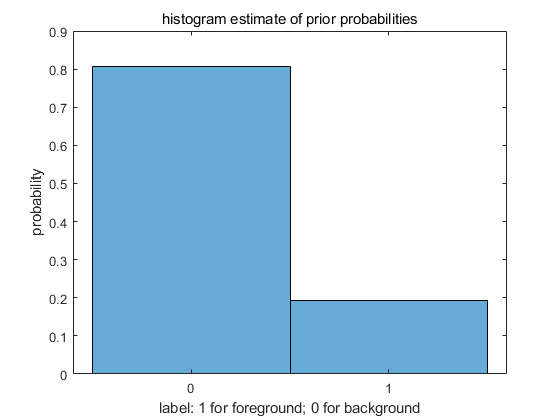

load('TrainingSamplesDCT_8_new.mat');
size_b=size(TrainsampleDCT_BG,1);
size_f=size(TrainsampleDCT_FG,1);
ls=ones(1,size_f);
ls=[ls zeros(1,size_b)];
histogram(ls,'Normalization','probability');
set(gca,'XTick',[0 1] );
xlabel("label: 1 for foreground; 0 for background");
ylabel("probability");
title('histogram estimate of prior probabilities');

we can see from the histogram,** P(grass)=0.8081** and **P(cheetah)=0.1919**.

ii. From problem 2, we can see the MLE for the prior parameter is equal to **Ck/n**, where Ck is the number of times the observe is k (k {0,1}), and n is the total number of observation. Therefore **P(grass)=1053/(1053+250)=0.8081**, **P(cheetah)=250/(1053+250)=0.1919**. This result is consistant to our last homwork's calculation. So last week I used the proportion of each class as the prior probability of that class.

b)

The following code computes MLE of the parameters of both class conditional densities and plot the Gaussian distribution for each class(red line for cheetah and blue line for grass). 

 By observing these 64 graphs, I think the** best 8 features are feature: [1, 14,  22,  25,  27,  32,  40, 48]**  and the **worst 8 features are feature: [2, 3, 4, 5, 59, 62, 63, 64]. **There plots show as follow:

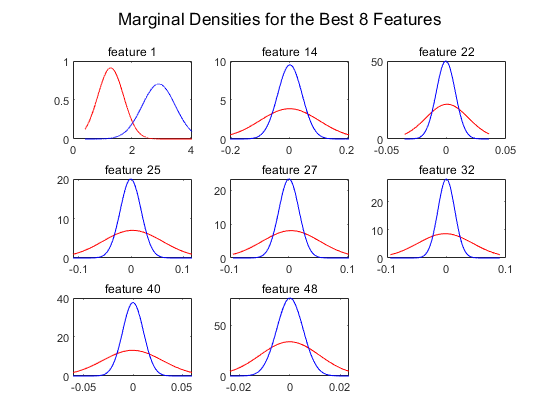

gx=[1,14,22,25,27,32,40,48];
bx=[2,3,4,5,59,62,63,64];

good_x_b=TrainsampleDCT_BG(:,gx);
good_x_f=TrainsampleDCT_FG(:,gx);

bad_x_b=TrainsampleDCT_BG(:,bx);
bad_x_f=TrainsampleDCT_FG(:,bx);

figure();
plot_marginal_densities(good_x_f,good_x_b,3,1,'Marginal Densities for the Best 8 Features',[1, 14,  22,  25,  27,  32,  40, 48]);

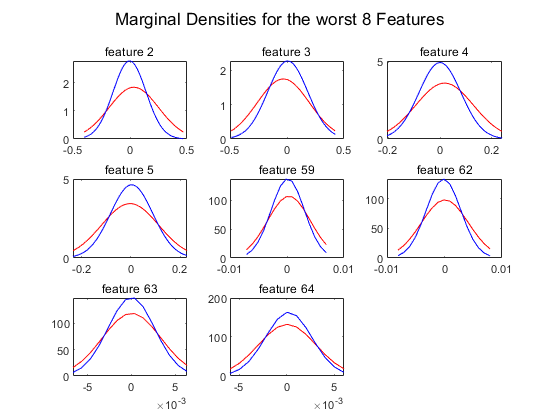

figure();
plot_marginal_densities(bad_x_f,bad_x_b,3,1,'Marginal Densities for the worst 8 Features',[2, 3, 4, 5, 59, 62, 63, 64]);

c) First we use all 64-dimensional gaussians to classify the image and calculate the error probabity. **P(error)= 0.0896**

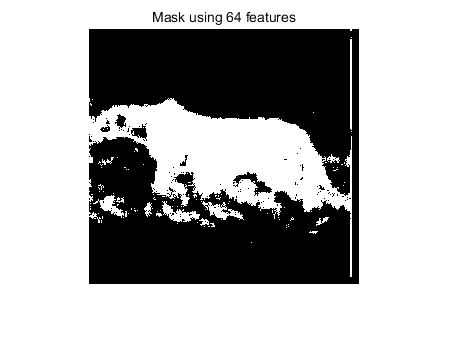

p_cheetah=250/1303;
p_grass=1053/1303;


u_b_64= mean(TrainsampleDCT_BG,1);
u_f_64= mean(TrainsampleDCT_FG,1);

u_b_8= mean(good_x_b,1);
u_f_8= mean(good_x_f,1);

sig_b_64= cov(TrainsampleDCT_BG);
sig_f_64= cov(TrainsampleDCT_FG);

sig_b_8= cov(good_x_b);
sig_f_8= cov(good_x_f);
%convert each block into an array
I=imread('cheetah.bmp');
I=im2double(I);
A= zeros(255,270);
for j=1:248
    for i=1:263
        each = I(j:j+7,i:i+7);
        each = dct2(each);
        each = zigzag_scan(each);
        if joint_gaussian(each,u_f_64,sig_f_64,p_cheetah)<joint_gaussian(each,u_b_64,sig_b_64,p_grass)
            A(j,i)=1;
        end
    end
end
figure();
imshow(A)
title("Mask using 64 features")


check=imread('cheetah_mask.bmp');
check=im2double(check);
error = sum(sum(xor(check, A))) / (255*270)

error = 0.0896

Now we use the best 8 features to do this again and calculate the probability of error:

**P(error) = 0.0564**

We can see the performance of best 8 features is better than using all 64 feautures. This is because with in those 64 features, there are some features that have similar gaussian distribution across two classes and therefore mislead the decision rule. Therefore by only selecting features with obviously dividable distributions can enhance the performance.

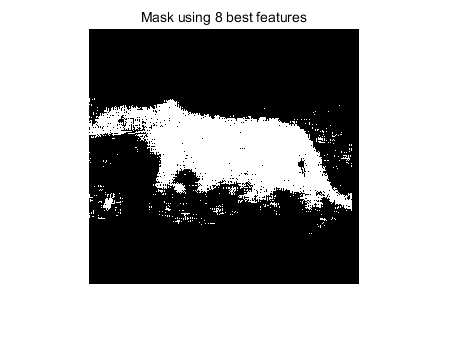

I=imread('cheetah.bmp');
I=im2double(I);
A= zeros(255,270);
for j=1:248
    for i=1:263
        each = I(j:j+7,i:i+7);
        each = dct2(each);
        each = zigzag_scan(each);
        each = each(:,gx);
        if joint_gaussian(each,u_f_8,sig_f_8,p_cheetah)<joint_gaussian(each,u_b_8,sig_b_8,p_grass)
            A(j,i)=1;
        end
    end
end
figure();
imshow(A)
title("Mask using 8 best features")

error = sum(sum(xor(check, A))) / (255*270)

error = 0.0564

Helper funcitons are below:

function joint_prob=joint_gaussian(x,u,sigma,prior)
    u=u.';
    each=x.';
    d_x_y=transpose(each-u)*inv(sigma)*(each-u);
    alpha=log((2*pi)^(size(x,2))*det(sigma))-2*log(prior);
    joint_prob=d_x_y+alpha;
end

function A=zigzag_scan(m)
    ZigZagPattern=[
        0   1   5   6  14  15  27  28;
        2   4   7  13  16  26  29  42;
        3   8  12  17  25  30  41  43;
        9  11  18  24  31  40  44  53;
        10  19  23  32  39  45  52  54;
        20  22  33  38  46  51  55  60;
        21  34  37  47  50  56  59  61;
        35  36  48  49  57  58  62  63
        ];
    ZigZagPattern=ZigZagPattern+1;
    A=zeros(1,64);
    for i=1:8
        for j=1:8
            A(ZigZagPattern(i,j))=m(i,j);
        end
    end
end

function [m,xstd]=my_mle(x)
    m=mean(x);
    xstd=std(x);
end

function a=plot_marginal_densities(X_FG,X_BG,n,er,stitle,ftitle)
    for i=1:n^2-er
        xi_f=X_FG(:,i);
        xi_b=X_BG(:,i);
        
        [mean_f,std_f]=my_mle(xi_f);
        [mean_b,std_b]=my_mle(xi_b);
        
        subplot(n,n,i);
        x=min(mean_f-2*std_f,mean_b-2*std_b):.001:max(mean_f+2*std_f,mean_b+2*std_b);
        y_f=normpdf(x,mean_f,std_f);
        y_b=normpdf(x,mean_b,std_b);
        plot(x,y_f,'r');
        hold on
        plot(x,y_b,'b');
        title(append('feature ',int2str(ftitle(i))));
        hold off;
    end
    sgtitle(stitle)
end